# SCARA Manipulator Study

% Find the models and helpers relative to this script.
clear all
close all
clc

projectRoot = fileparts(mfilename('fullpath'));
addpath(fullfile(projectRoot, 'kinematics'), ...
        fullfile(projectRoot, 'trajectory'), ...
        fullfile(projectRoot, 'control'));

## SCARA parameters and manipulability

% Link lengths and base height [m]
d0 = 1;
a1 = 0.5;
a2 = 0.5;
l1 = 0.25;
l2 = 0.25;

% Link and payload masses [kg]
ml1 = 20;
ml2 = 20;
ml3 = 10;
ml4=0;

% Inertias [kg·m²]
Il1 = 4;
Il2 = 4;
Il3 = 0;
Il4 = 1;

% Joint transmission ratios
kr1 = 1;
kr2 = 1;
kr3 = 50;
kr4 = 20;

% Inertias [kg·m²]
Im1 = 0.01;
Im2 = 0.01;
Im3 = 0.005;
Im4 = 0.001;

% Motor-side viscous friction
Fm1 = 0.00005;
Fm2 = 0.00005;
Fm3 = 0.01;
Fm4 = 0.005;

Tc = 0.001;

% Joint angles used for the ellipsoid plots.

theta1 = [pi/4; -pi*4/9];
theta2 = [pi/4; -pi/6];
theta3 = [pi/3; -pi/3];
theta4 = [pi/6; -pi/9];

px = a1*cos(theta1(1))+a2*cos(theta1(1)+theta1(2));
py = a1*sin(theta1(1))+a2*sin(theta1(1)+theta1(2));

J = [-a1*sin(theta1(1))-a2*sin(theta1(1)+theta1(2)) -a2*sin(theta1(1)+theta1(2));
      a1*cos(theta1(1))+a2*cos(theta1(1)+theta1(2))  a2*cos(theta1(1)+theta1(2))];

## Trajectory planning

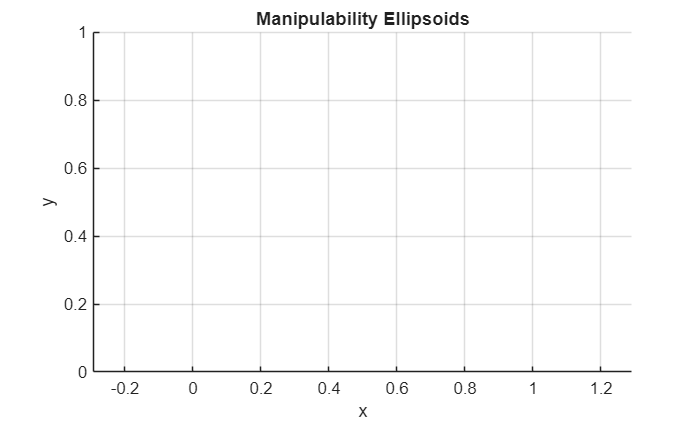

% Waypoints are listed as [x, y, z, phi].
tk = 0 : 5 : 5*24;

    point1  = [0.6   0.3  0.3  0];
    point2  = [0.9   0.35 0.45 0];
    point3  = [1.0   0.50 0.60 0];
    point4  = [1.2   0.70 0.90 pi/4];
    point5  = [1.25  0.95 1.00 pi/6];
    point6  = [1.0   0.80 0.85 pi/6];
    point7  = [0.90  0.75 0.60 pi/6];
    point8  = [0.60  0.90 0.90 pi/6];
    point9  = [0.45  0.70 0.90 pi/6];
    point10 = [0.35  0.88 0.65 pi/6];
    point11 = [0.25  0.88 0.50 pi/6];

    % The path follows arcs between waypoints 12, 13, and 14.
    point12 = [0.3   0.9  0.5  pi/6];
    point13 = [0.0   0.9  0.5  pi/6];
    point14 = [-0.2  0.9  0.5  pi/4];

    point15 = [-0.35 0.78 0.70 pi/4];
    point16 = [-0.35 0.60 0.70 pi/4];
    point17 = [-0.65 0.40 0.55 pi/4];
    point18 = [-0.80 0.35 0.35 pi/4];
    point19 = [-0.40 0.25 0.15 pi/4];
    point20 = [0.0   0.30 0.25 pi/4];
    point21 = [0.20  0.45 0.35 pi/4];
    point22 = [0.45  0.60 0.40 pi/6];

point23 = [0.6   0.3  0.3  0];

p =(1/2.5)*[point1(1:3);
    point2(1:3);
    point3(1:3);
    point4(1:3);
    point5(1:3);
    point6(1:3);
    point7(1:3);
    point8(1:3);
    point9(1:3);
    point10(1:3);
    point11(1:3);
    point12(1:3);
    point13(1:3);
    point14(1:3);
    point15(1:3);
    point16(1:3);
    point17(1:3);
    point18(1:3);
    point19(1:3);
    point20(1:3);
    point21(1:3);
    point22(1:3);
    point23(1:3);
    ]';

grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z');
title('Manipulability Ellipsoids');

[s1 ,s1dot, s1dotdot] = trapezoidal_path_profile(p(:,1),p(:,2),tk(1),tk(2),tk(end),0,0,0,0,0);
P1 = p(:,1)+(s1.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P1dot = (s1dot.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));
P1dotdot = (s1dotdot.*(p(:,2)-p(:,1)))/norm(p(:,2)-p(:,1));

[s2 ,s2dot, s2dotdot] = trapezoidal_path_profile(p(:,2),p(:,3),tk(2),tk(3),tk(end),0,1,0,0,1.8);
P2 = (s2.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P2dot = (s2dot.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));
P2dotdot = (s2dotdot.*(p(:,3)-p(:,2)))/norm(p(:,3)-p(:,2));

[s3,s3dot,s3dotdot] = trapezoidal_path_profile(p(:,3),p(:,4),tk(3),tk(4),tk(end),0,0,0,0,0);
P3 = p(:,3) + (s3.*(p(:,4)-p(:,3)))/norm(p(:,4)-p(:,3));
P3dot = (s3dot.*(p(:,4)-p(:,3)))/norm(p(:,4)-p(:,3));
P3dotdot = (s3dotdot.*(p(:,4)-p(:,3)))/norm(p(:,4)-p(:,3));

[s4,s4dot,s4dotdot] = trapezoidal_path_profile(p(:,4),p(:,5),tk(4),tk(5),tk(end),0,0,0,0,0);
P4 = p(:,4) + (s4.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));
P4dot = (s4dot.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));

P4dotdot = (s4dotdot.*(p(:,5)-p(:,4)))/norm(p(:,5)-p(:,4));

[s5,s5dot,s5dotdot] = trapezoidal_path_profile(p(:,5),p(:,6),tk(5),tk(6),tk(end),0,1,0,0,1);
P5 = (s5.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P5dot = (s5dot.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));
P5dotdot = (s5dotdot.*(p(:,6)-p(:,5)))/norm(p(:,6)-p(:,5));

[s6,s6dot,s6dotdot] = trapezoidal_path_profile(p(:,6),p(:,7),tk(6),tk(7),tk(end),0,0,0,0,0);
P6 = (s6.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P6dot = (s6dot.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));
P6dotdot = (s6dotdot.*(p(:,7)-p(:,6)))/norm(p(:,7)-p(:,6));

[s7,s7dot,s7dotdot] = trapezoidal_path_profile(p(:,7),p(:,8),tk(7),tk(8),tk(end),0,0,0,0,0);
P7 = (s7.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P7dot = (s7dot.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));
P7dotdot = (s7dotdot.*(p(:,8)-p(:,7)))/norm(p(:,8)-p(:,7));

[s8,s8dot,s8dotdot] = trapezoidal_path_profile(p(:,8),p(:,9),tk(8),tk(9),tk(end),0,1,0,0,1.5);
P8 = (s8.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P8dot = (s8dot.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));
P8dotdot = (s8dotdot.*(p(:,9)-p(:,8)))/norm(p(:,9)-p(:,8));

[s9,s9dot,s9dotdot] = trapezoidal_path_profile(p(:,9),p(:,10),tk(9),tk(10),tk(end),0,0,0,0,0);
P9 =(s9.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P9dot = (s9dot.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));
P9dotdot = (s9dotdot.*(p(:,10)-p(:,9)))/norm(p(:,10)-p(:,9));

[s10, s10dot, s10dotdot] = trapezoidal_path_profile(p(:,10), p(:,11), tk(10), tk(11), tk(end), 0, 0, 0, 0, 0);
P10 = (s10 .* (p(:,11) - p(:,10))) / norm(p(:,11) - p(:,10));
P10dot = (s10dot .* (p(:,11) - p(:,10))) / norm(p(:,11) - p(:,10));
P10dotdot = (s10dotdot .* (p(:,11) - p(:,10))) / norm(p(:,11) - p(:,10));

[s11, s11dot, s11dotdot] = trapezoidal_path_profile(p(:,11), p(:,12), tk(11), tk(12), tk(end), 0, 0, 0, 0, 0);
P11 = p(:,11)+(s11 .* (p(:,12) - p(:,11))) / norm(p(:,12) - p(:,11));
P11dot = (s11dot .* (p(:,12) - p(:,11))) / norm(p(:,12) - p(:,11));
P11dotdot = (s11dotdot .* (p(:,12) - p(:,11))) / norm(p(:,12) - p(:,11));

R = [1 0 0;
     0 -1 0
      0 0 -1];

rho = sum(abs(p(:,12) - p(:,13)))/2;
C = (p(:,12) + p(:,13)) ./ 2;

[s12, s12dot, s12dotdot] = trapezoidal_path_profile(p(:,12), p(:,13), tk(12), tk(13), tk(end), 1, 0, rho, pi, 0);

P_primo = [rho * cos(s12 / rho); rho * sin(s12 / rho); zeros(1, length(s12))];
P12 = C + R * P_primo;
P_primodot = [-s12dot .* sin(s12 / rho); s12dot .* cos(s12 / rho); zeros(1, length(s12))];
P12dot = R * P_primodot;
P_primodotdot = [-((s12dot .^ 2) .* cos(s12 / rho)) / rho - s12dotdot .* sin(s12 / rho); -((s12dot .^ 2) .* sin(s12 / rho)) / rho + s12dotdot .* cos(s12 / rho); zeros(1, length(s12))];
P12dotdot = R * P_primodotdot;

R = [1 0 0;
     0 0 1
      0 -1 0];
rho = sum(abs(p(:,13) - p(:,14)))/2;
C = (p(:,13) + p(:,14)) ./ 2;

[s13, s13dot, s13dotdot] = trapezoidal_path_profile(p(:,13), p(:,14), tk(13), tk(14), tk(end), 1, 0, rho, pi, 0);

P_primo = [rho * cos(s13 / rho); rho * sin(s13 / rho); zeros(1, length(s13))];
P13 = C + R * P_primo;
P_primodot = [-s13dot .* sin(s13 / rho); s13dot .* cos(s13 / rho); zeros(1, length(s13))];
P13dot = R * P_primodot;
P_primodotdot = [-((s13dot .^ 2) .* cos(s13 / rho)) / rho - s13dotdot .* sin(s13 / rho); -((s13dot .^ 2) .* sin(s13 / rho)) / rho + s12dotdot .* cos(s13 / rho); zeros(1, length(s13))];
P13dotdot = R * P_primodotdot;

[s14, s14dot, s14dotdot] = trapezoidal_path_profile(p(:,14), p(:,15), tk(14), tk(15), tk(end), 0, 0, 0, 0, 0);
P14 = (s14 .* (p(:,15) - p(:,14))) / norm(p(:,15) - p(:,14));
P14dot = (s14dot .* (p(:,15) - p(:,14))) / norm(p(:,15) - p(:,14));
P14dotdot = (s14dotdot .* (p(:,15) - p(:,14))) / norm(p(:,15) - p(:,14));

[s15, s15dot, s15dotdot] = trapezoidal_path_profile(p(:,15), p(:,16), tk(15), tk(16), tk(end), 0, 1, 0, 0, 1.5);
P15 = (s15 .* (p(:,16) - p(:,15))) / norm(p(:,16) - p(:,15));
P15dot = (s15dot .* (p(:,16) - p(:,15))) / norm(p(:,16) - p(:,15));
P15dotdot = (s15dotdot .* (p(:,16) - p(:,15))) / norm(p(:,16) - p(:,15));

[s16, s16dot, s16dotdot] = trapezoidal_path_profile(p(:,16), p(:,17), tk(16), tk(17), tk(end), 0, 0, 0, 0, 0);
P16 = (s16 .* (p(:,17) - p(:,16))) / norm(p(:,17) - p(:,16));
P16dot = (s16dot .* (p(:,17) - p(:,16))) / norm(p(:,17) - p(:,16));
P16dotdot = (s16dotdot .* (p(:,17) - p(:,16))) / norm(p(:,17) - p(:,16));

[s17, s17dot, s17dotdot] = trapezoidal_path_profile(p(:,17), p(:,18), tk(17), tk(18), tk(end), 0, 0, 0, 0, 0);
P17 = (s17 .* (p(:,18) - p(:,17))) / norm(p(:,18) - p(:,17));
P17dot = (s17dot .* (p(:,18) - p(:,17))) / norm(p(:,18) - p(:,17));
P17dotdot = (s17dotdot .* (p(:,18) - p(:,17))) / norm(p(:,18) - p(:,17));

[s18, s18dot, s18dotdot] = trapezoidal_path_profile(p(:,18), p(:,19), tk(18), tk(19), tk(end), 0, 1, 0, 0, 1.5);
P18 = (s18 .* (p(:,19) - p(:,18))) / norm(p(:,19) - p(:,18));
P18dot = (s18dot .* (p(:,19) - p(:,18))) / norm(p(:,19) - p(:,18));
P18dotdot = (s18dotdot .* (p(:,19) - p(:,18))) / norm(p(:,19) - p(:,18));

[s19, s19dot, s19dotdot] = trapezoidal_path_profile(p(:,19), p(:,20), tk(19), tk(20), tk(end), 0, 0, 0, 0, 0);
P19 = (s19 .* (p(:,20) - p(:,19))) / norm(p(:,20) - p(:,19));
P19dot = (s19dot .* (p(:,20) - p(:,19))) / norm(p(:,20) - p(:,19));
P19dotdot = (s19dotdot .* (p(:,20) - p(:,19))) / norm(p(:,20) - p(:,19));

[s20, s20dot, s20dotdot] = trapezoidal_path_profile(p(:,20), p(:,21), tk(20), tk(21), tk(end), 0, 0, 0, 0, 0);
P20 = (s20 .* (p(:,21) - p(:,20))) / norm(p(:,21) - p(:,20));
P20dot = (s20dot .* (p(:,21) - p(:,20))) / norm(p(:,21) - p(:,20));
P20dotdot = (s20dotdot .* (p(:,21) - p(:,20))) / norm(p(:,21) - p(:,20));

[s21, s21dot, s21dotdot] = trapezoidal_path_profile(p(:,21), p(:,22), tk(21), tk(22), tk(end), 0, 0, 0, 0, 0);
P21 = (s21 .* (p(:,22) - p(:,21))) / norm(p(:,22) - p(:,21));
P21dot = (s21dot .* (p(:,22) - p(:,21))) / norm(p(:,22) - p(:,21));
P21dotdot = (s21dotdot .* (p(:,22) - p(:,21))) / norm(p(:,22) - p(:,21));

[s22, s22dot, s22dotdot] = trapezoidal_path_profile(p(:,22), p(:,23), tk(22), tk(23), tk(end), 0, 0, 0, 0, 0);
P22 = (s22 .* (p(:,23) - p(:,22))) / norm(p(:,23) - p(:,22));
P22dot = (s22dot .* (p(:,23) - p(:,22))) / norm(p(:,23) - p(:,22));
P22dotdot = (s22dotdot .* (p(:,23) - p(:,22))) / norm(p(:,23) - p(:,22));

P_A = P1+P2;
P_B = P4+P5+P6+P7+P8+P9+P10;
P_C = P13+P14+P15+P16+P17+P18+P19+P20+P21+P22;
P = [P_A(:,1:tk(3)*1000) P3(:,tk(3)*1000+1:tk(4)*1000) P_B(:,tk(4)*1000+1:tk(11)*1000) P11(:,tk(11)*1000+1:tk(12)*1000) P12(:,tk(12)*1000+1:tk(13)*1000) P_C(:,tk(13)*1000+1:end)];

P_Adot = P1dot+P2dot;
P_Bdot = P4dot + P5dot + P6dot + P7dot + P8dot + P9dot + P10dot ;
P_Cdot = P13dot + P14dot + P15dot + P16dot + P17dot + P18dot + P19dot + P20dot + P21dot + P22dot;
Pdot = [P_Adot(:,1:tk(3)*1000) P3dot(:,tk(3)*1000+1:tk(4)*1000) P_Bdot(:,tk(4)*1000+1:tk(11)*1000) P11dot(:,tk(11)*1000+1:tk(12)*1000) P12dot(:,tk(12)*1000+1:tk(13)*1000) P_Cdot(:,tk(13)*1000+1:end)];

P_Adotdot = P1dotdot+P2dotdot;
P_Bdotdot =  P4dotdot + P5dotdot + P6dotdot + P7dotdot + P8dotdot + P9dotdot + P10dotdot ;
P_Cdotdot = P11dotdot + P12dotdot + P13dotdot + P14dotdot + P15dotdot + P16dotdot + P17dotdot + P18dotdot + P19dotdot + P20dotdot + P21dotdot + P22dotdot;
Pdotdot = [P_Adotdot(:,1:tk(3)*1000) P3dotdot(:,tk(3)*1000+1:tk(4)*1000) P_Bdotdot(:,tk(4)*1000+1:end)];
Pdotdot = [P_Adotdot(:,1:tk(3)*1000) P3dotdot(:,tk(3)*1000+1:tk(4)*1000) P_Bdotdot(:,tk(4)*1000+1:tk(11)*1000) P11dotdot(:,tk(11)*1000+1:tk(12)*1000) P12dotdot(:,tk(12)*1000+1:tk(13)*1000) P_Cdotdot(:,tk(13)*1000+1:end)];

s = s1+s2+s3+s4+s5+s6+s7+s8+s9+s10+s11+s12+s13+s14+s15+s16+s17+s18+s19+s20+s21+s22;
sdot = s1dot+s2dot+s3dot+s4dot+s5dot+s6dot+s7dot+s8dot+s9dot+s10dot+s11dot+s12dot+s13dot+s14dot+s15dot+s16dot+s17dot+s18dot+s19dot+s20dot+s21dot+s22dot;
sdotdot = s1dotdot+s2dotdot+s3dotdot+s4dotdot+s5dotdot+s6dotdot+s7dotdot+s8dotdot+s9dotdot+s10dotdot+s11dotdot+s12dotdot+s13dotdot+s14dotdot+s15dotdot+s16dotdot+s17dotdot+s18dotdot+s19dotdot+s20dotdot+s21dotdot+s22dotdot;

% Orientation changes have their own timing.
phi = [0 pi/2 pi 3*pi/2 2*pi];

[phi1 ,phi1dot, phi1dotdot] = trapezoidal_path_profile(phi(1),phi(2),tk(1),tk(2),tk(end),0,0,0,0,0);
[phi2 ,phi2dot, phi2dotdot] = trapezoidal_path_profile(phi(2),phi(3),tk(4),tk(8),tk(end),0,0,0,0,0);
[phi3 ,phi3dot, phi3dotdot] = trapezoidal_path_profile(phi(3),phi(4),tk(9),tk(10),tk(end),0,0,0,0,0);
[phi4 ,phi4dot, phi4dotdot] = trapezoidal_path_profile(phi(4),phi(5),tk(18),tk(20),tk(end),0,0,0,0,0);

phe = phi(1)+phi1.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4.*(phi(5)-phi(4))/norm(phi(5)-phi(4));
phedot = phi1dot.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2dot.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3dot.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4dot.*(phi(5)-phi(4))/norm(phi(5)-phi(4));
phedotdot = phi1dotdot.*(phi(2)-phi(1))/norm(phi(2)-phi(1)) + phi2dotdot.*(phi(3)-phi(2))/norm(phi(3)-phi(2)) + phi3dotdot.*(phi(4)-phi(3))/norm(phi(4)-phi(3)) + phi4dotdot.*(phi(5)-phi(4))/norm(phi(5)-phi(4));

t = linspace(0, tk(end), tk(end)*1000+1);
tf_total = tk(end);

% The models take [x; y; z; phi] and its time derivatives.
xd = timeseries([P;phe],t);
xddot = timeseries([Pdot;phedot],t);
xddotdot = timeseries([Pdotdot;phedotdot],t);

figure('Name', '3D Trajectory with Points', 'NumberTitle', 'off');
hold on;
plot3(P(1,:), P(2,:), P(3,:), 'Color', [0.2 0.7 1.0], 'LineWidth', 2);
via_indices = [2,5,8,15,18];
exact_indices = setdiff(1:size(p, 2), via_indices);
plot3(p(1, via_indices), p(2, via_indices), p(3, via_indices), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'r');
plot3(p(1, exact_indices), p(2, exact_indices), p(3, exact_indices), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'b');
axis equal; grid on; view(3);
title('Trajectory');
xlabel('x'); ylabel('y'); zlabel('z');
legend('Trajectory', 'Via Points', 'Exact Points');
hold off;

figure('Name', '2D Trajectory (XY Plane)', 'NumberTitle', 'off');
hold on;
plot(P(1,:), P(2,:), 'Color', [0.2 0.7 1.0], 'LineWidth', 2);
plot(p(1, via_indices), p(2, via_indices), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'r');
plot(p(1, exact_indices), p(2, exact_indices), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'b');
axis equal; grid on;
title('2D Trajectory (XY Plane)');
xlabel('x'); ylabel('y');
legend('Trajectory', 'Via Points', 'Exact Points');
hold off;

figure('Name', 'Path Parameter Profiles', 'NumberTitle', 'off');
subplot(3,1,1);
plot(t, s, 'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
grid on; xlabel('t [s]'); ylabel('$s$', 'Interpreter', 'latex'); title('$s(t)$', 'Interpreter', 'latex');
xlim([0 tf_total]);
subplot(3,1,2);
plot(t, sdot, 'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
grid on; xlabel('t [s]'); ylabel('$\dot{s}$', 'Interpreter', 'latex'); title('$\dot{s}(t)$', 'Interpreter', 'latex');
xlim([0 tf_total]);
subplot(3,1,3);
plot(t, sdotdot, 'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
grid on; xlabel('t [s]'); ylabel('$\ddot{s}$', 'Interpreter', 'latex'); title('$\ddot{s}(t)$', 'Interpreter', 'latex');
xlim([0 tf_total]);

figure('Name', 'Orientation Profiles', 'NumberTitle', 'off');
subplot(3,1,1)
hold on
plot(t, phe, 'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter','latex');
ylabel('$\phi$ [rad]', 'Interpreter','latex');
legend({'orient'}, 'Interpreter','latex');
grid on; xlim([0 tf_total]);
hold off
subplot(3,1,2)
hold on
plot(t, phedot,'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter','latex');
ylabel('$\dot{\phi}$ [rad/s]', 'Interpreter','latex');
legend({'orient vel'}, 'Interpreter','latex');
grid on; xlim([0 tf_total]);
hold off
subplot(3,1,3)
hold on
plot(t, phedotdot, 'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter','latex');
ylabel('$\ddot{\phi}$ [rad/s$^2$]', 'Interpreter','latex');
legend({'orient acc'}, 'Interpreter','latex');
grid on; xlim([0 tf_total]);
hold off

figure('Name', 'Desired Trajectory - Position', 'NumberTitle', 'off');
plot(t, P(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(t, P(2,:), 'b', 'LineWidth', 1.5);
plot(t, P(3,:), 'k', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$p_d$', 'Interpreter', 'latex');
legend({'$x$','$y$','$z$'}, 'Interpreter', 'latex');
xlim([0 tf_total]);
title('Desired Position');
grid on;
hold off;

figure('Name', 'Desired Trajectory - Orientation', 'NumberTitle', 'off');
plot(t, phe,'Color', [0.2 0.7 1.0], 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\phi_d$ [rad]', 'Interpreter', 'latex');
legend({'$\phi$'}, 'Interpreter', 'latex');
xlim([0 tf_total]);
title('Desired Orientation');
grid on;

figure('Name', 'Desired Trajectory - Velocity', 'NumberTitle', 'off');
plot(t, Pdot(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(t, Pdot(2,:), 'b', 'LineWidth', 1.5);
plot(t, Pdot(3,:), 'k', 'LineWidth', 1.5);
plot(t, phedot, 'g', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\dot{x}_d$', 'Interpreter', 'latex');
legend({'$\dot{x}$','$\dot{y}$','$\dot{z}$','$\dot{\phi}$'}, 'Interpreter', 'latex');
xlim([0 tf_total]);
title('Desired Velocity');
grid on;

figure('Name', 'Desired Trajectory - Acceleration', 'NumberTitle', 'off');
plot(t, Pdotdot(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(t, Pdotdot(2,:), 'b', 'LineWidth', 1.5);
plot(t, Pdotdot(3,:), 'k', 'LineWidth', 1.5);
plot(t, phedotdot, 'g', 'LineWidth', 1.5);
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\ddot{x}_d$', 'Interpreter', 'latex');
legend({'$\ddot{x}$','$\ddot{y}$','$\ddot{z}$','$\ddot{\phi}$'}, 'Interpreter', 'latex');
xlim([0 tf_total]);
title('Desired Acceleration');
grid on;

## CLIK with the inverse Jacobian

q0=[-0.8355, 2.5983,-0.8800,-1.7628];
K = eye(4)*1000;
out=sim("clik_jacobian_inverse.slx");

figure
plot(t,out.q.signals.values(1,:), 'black')
hold on
plot(t,out.q.signals.values(2,:), 'bl')
hold on
plot(t,out.q.signals.values(3,:), 'r')
hold on
plot(t,out.q.signals.values(4,:), 'Color', [0.2 0.7 1.0])
hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$q(t)$', 'Interpreter', 'latex');
title('Joint variables values');
xlim([0 24*5])
legend('q1','q2','q3','q4')
grid on
figure
plot(t,out.xe.signals.values(1,:), 'black')
hold on
plot(t,out.xe.signals.values(2,:), 'bl')
hold on
plot(t,out.xe.signals.values(3,:), 'r')
hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$x_e$', 'Interpreter', 'latex')
legend('x','y','z')
title('End effector position')
xlim([0 24*5])
grid on
hold off
plot(t,out.xe.signals.values(4,:), 'Color', [0.2 0.7 1.0])
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\phi_e$', 'Interpreter', 'latex')
legend('$\phi_e$', 'Interpreter', 'latex')
title('End effector orientation')
xlim([0 24*5])
grid on

figure
plot3(out.xe.signals.values(1,:),out.xe.signals.values(2,:),out.xe.signals.values(3,:), 'r')
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','blue')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

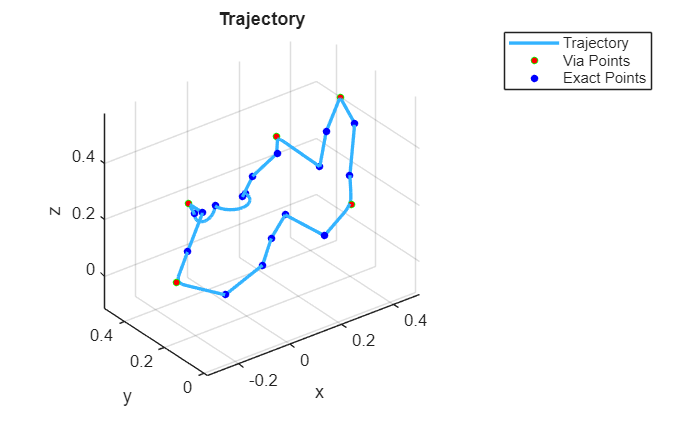

figure
plot(t,out.e.signals.values(1,:), 'black')
hold on
plot(t,out.e.signals.values(2,:), 'blue')
hold on
plot(t,out.e.signals.values(3,:), 'red')
hold on
plot(t,out.e.signals.values(4,:), 'Color', [0.2 0.7 1.0])

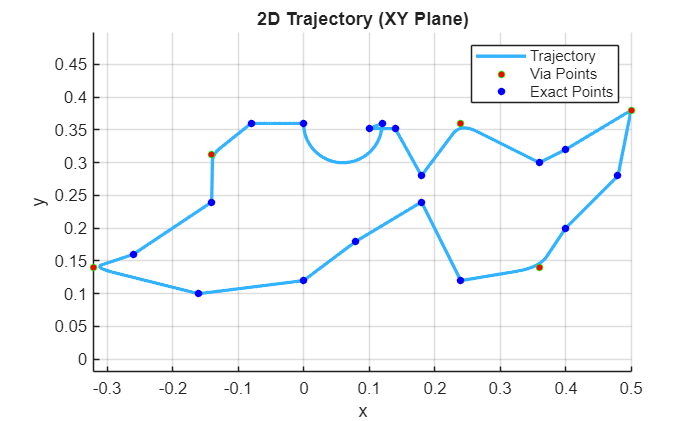

hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$e(t)$', 'Interpreter', 'latex')
xlim([0 24*5])
ylim([-1e-7, 1e-7])
legend('e_x','e_y','e_z','e_{\phi}')
title('Position tracking error')
grid on
hold off
w_inv = (sin(out.q.signals.values(2,:))).^2
plot(t,w_inv)

## CLIK with the Jacobian pseudoinverse

% Leave z free and use the extra degree of freedom to improve manipulability.
Pp = P(1:2,:);
Ppdot = Pdot(1:2,:);
xdp = timeseries([Pp;phe],t);
xdpdot = timeseries([Ppdot;phedot],t);
K_pinv = diag([10,10,10]);
k0 = 0.05;
out=sim("clik_jacobian_pseudoinverse.slx");

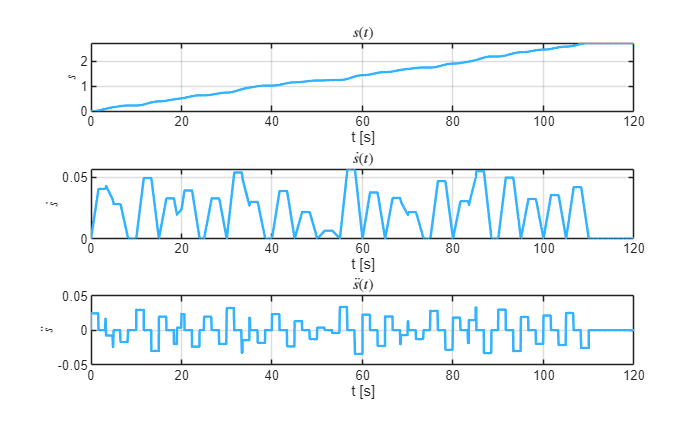

figure
plot(t,out.q_pinv.signals.values(1,:), 'black')
hold on
plot(t,out.q_pinv.signals.values(2,:), 'blue')
hold on
plot(t,out.q_pinv.signals.values(3,:), 'red')
hold on

plot(t,out.q_pinv.signals.values(4,:), 'Color', [0.2 0.7 1.0])
hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$q(t)$', 'Interpreter', 'latex');
title('Joint variables values');
legend('q1','q2','q3','q4')
grid on

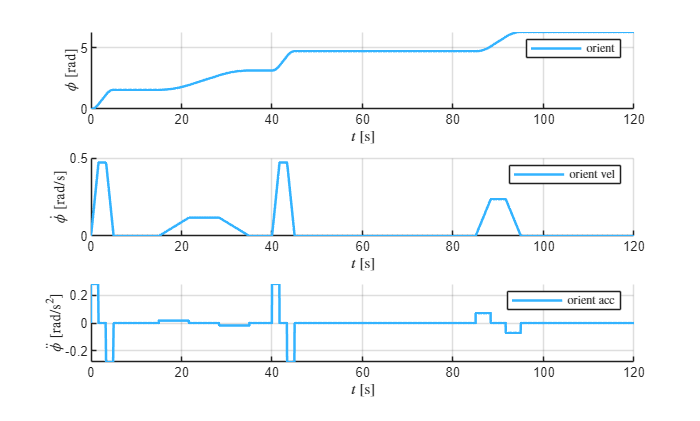

figure
plot(t,out.xe_pinv.signals.values(1,:), 'black')
hold on
plot(t,out.xe_pinv.signals.values(2,:), 'bl')
hold on
plot(t,out.xe_pinv.signals.values(3,:), 'r')
hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$x_e$', 'Interpreter', 'latex')
legend('x','y','z')
title('End effector position')
xlim([0 24*5])
grid on
hold off
plot(t,out.xe_pinv.signals.values(4,:), 'Color', [0.2 0.7 1.0])
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\phi_e$', 'Interpreter', 'latex')
legend('$\phi_e$', 'Interpreter', 'latex')
title('End effector orientation')
xlim([0 24*5])

grid on

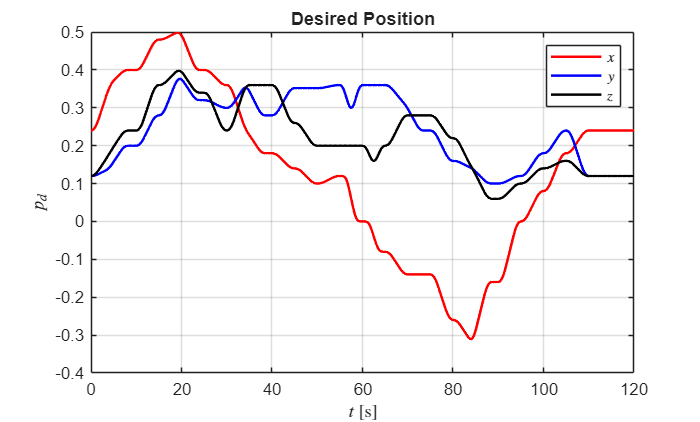

figure
plot(t,out.e_pinv.signals.values(1,:), 'black')
hold on
plot(t,out.e_pinv.signals.values(2,:), 'blue')
hold on
plot(t,out.e_pinv.signals.values(3,:), 'red')
hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$e(t)$', 'Interpreter', 'latex');
legend('e_x','e_y','e_z','e_{\phi}')
title('Position tracking error')
grid on

xlim([0 120])
ylim([-1.5e-5 1.5e-5])
w_pinv = (sin(out.q_pinv.signals.values(2,:))).^2;

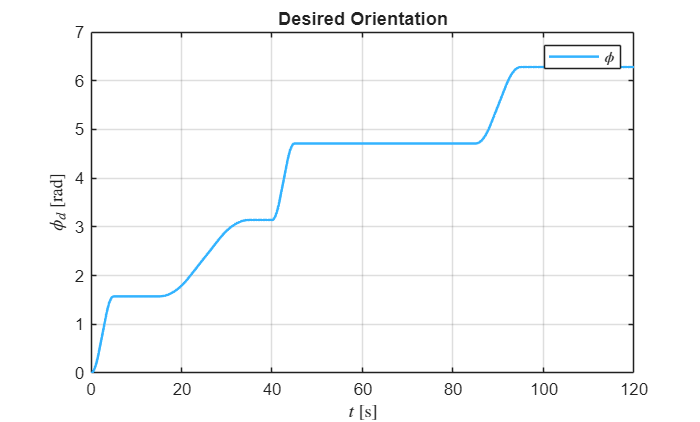

figure
plot(t,w_inv)
hold on
xlim([0 24*5])
ylim([0 1.2])
plot(t,w_pinv)
title('Manipulability measure');

legend('$\omega$', 'Interpreter', 'latex')
grid on

## CLIK with the Jacobian transpose

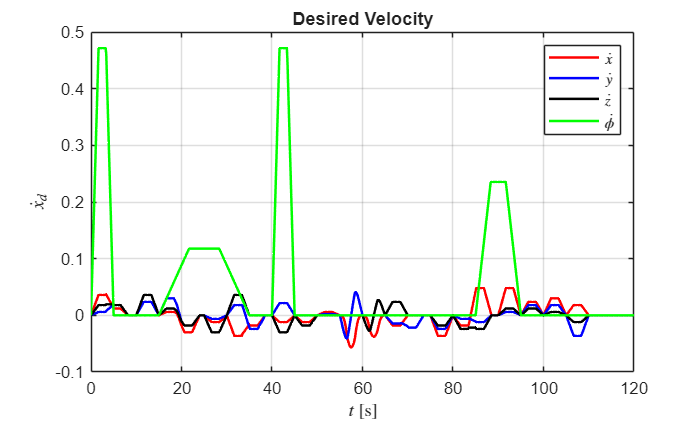

K_trasp = diag([820 500 600 500]);

out=sim("clik_jacobian_transpose.slx");
figure
plot(t,out.q_trasp.signals.values(:,1), 'black')
hold on
plot(t,out.q_trasp.signals.values(:,2), 'blue')
hold on
plot(t,out.q_trasp.signals.values(:,3), 'red')
hold on
plot(t,out.q_trasp.signals.values(:,4), 'Color', [0.2 0.7 1.0])

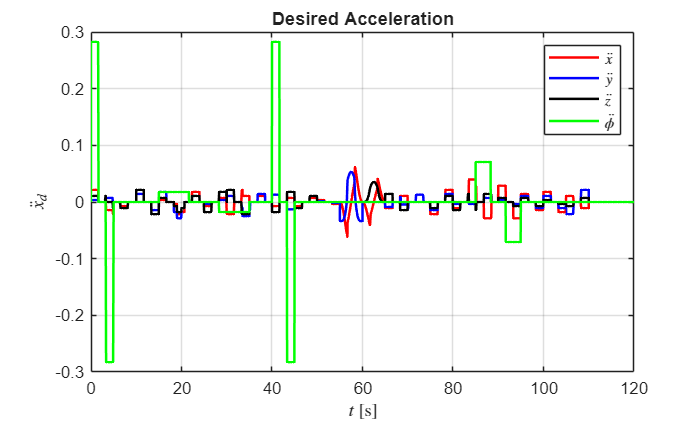

hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$q(t)$', 'Interpreter', 'latex')
legend('x','y','z')
title('Joint variables values')
xlim([0 24*5])
legend('q1','q2','q3','q4')
grid on
figure
plot(t,out.xe_trasp.signals.values(1,:), 'black')
hold on
plot(t,out.xe_trasp.signals.values(2,:), 'bl')
hold on
plot(t,out.xe_trasp.signals.values(3,:), 'r')
hold on

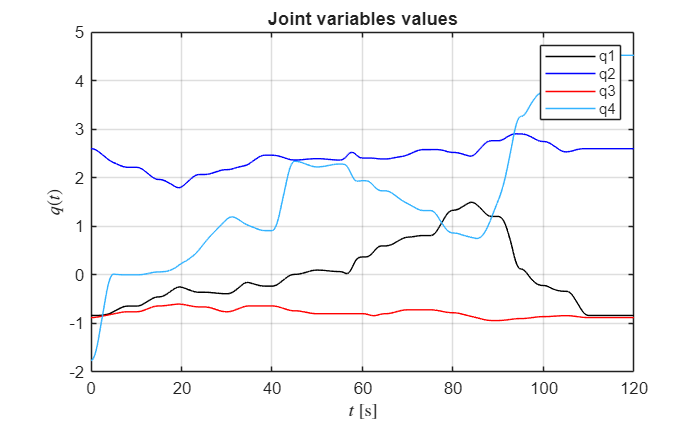

xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$x_e$', 'Interpreter', 'latex')
legend('x','y','z')
title('End effector position')
xlim([0 24*5])
grid on
hold off
plot(t,out.xe_trasp.signals.values(4,:), 'Color', [0.2 0.7 1.0])
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\phi_e$', 'Interpreter', 'latex')
legend('$\phi_e$', 'Interpreter', 'latex')
title('End effector orientation')
xlim([0 24*5])
grid on

figure
plot3(out.xe_trasp.signals.values(1,:),out.xe_trasp.signals.values(2,:),out.xe_trasp.signals.values(3,:), 'r')
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','b')

figure
plot(t,out.e_trasp.signals.values(1,:), 'black')
hold on
plot(t,out.e_trasp.signals.values(2,:), 'blue')
hold on
plot(t,out.e_trasp.signals.values(3,:), 'red')
hold on
plot(t,out.e_trasp.signals.values(4,:), 'Color', [0.2 0.7 1.0])
hold on

xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$e(t)$', 'Interpreter', 'latex')
xlim([0 24*5])
ylim([-10e-3, 10e-3])
title('Position tracking error')
legend('e_x','e_y','e_z','e_{\phi}')
grid on

## Second-order CLIK

% The robust and adaptive controllers use these joint references.
Kp = diag([100,100,100,100]);
Kd = diag([20,20,20,20]);
out=sim("clik_second_order.slx");

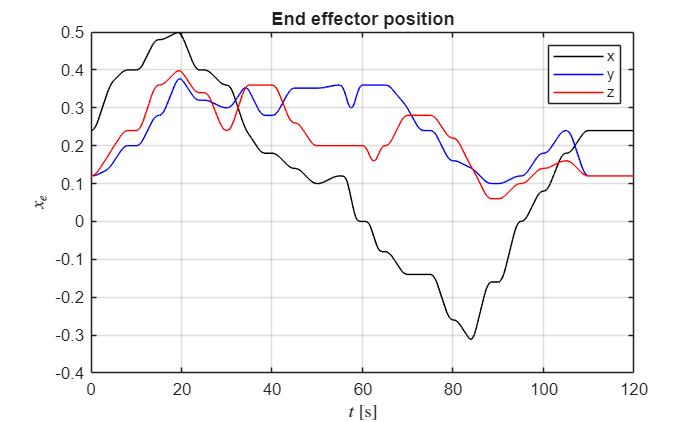

figure

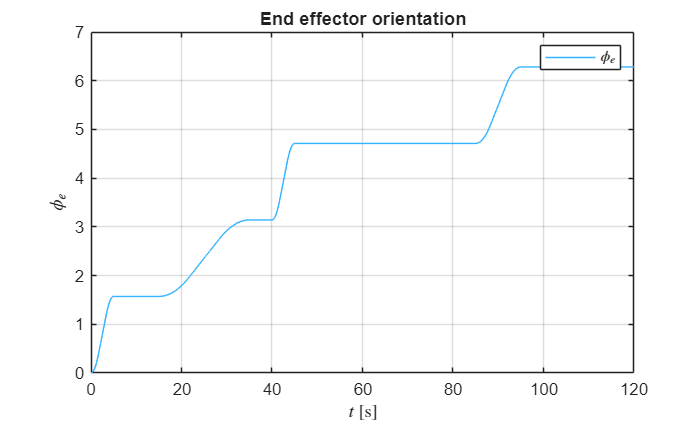

plot(t,out.q_sec.signals.values(1,:), 'black')
hold on
plot(t,out.q_sec.signals.values(2,:), 'bl')
hold on
plot(t,out.q_sec.signals.values(3,:), 'r')
hold on
plot(t,out.q_sec.signals.values(4,:), 'Color', [0.2 0.7 1.0])

hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$q(t)$', 'Interpreter', 'latex');
title('Joint variables values');
xlim([0 24*5])
legend('q1','q2','q3','q4')
grid on

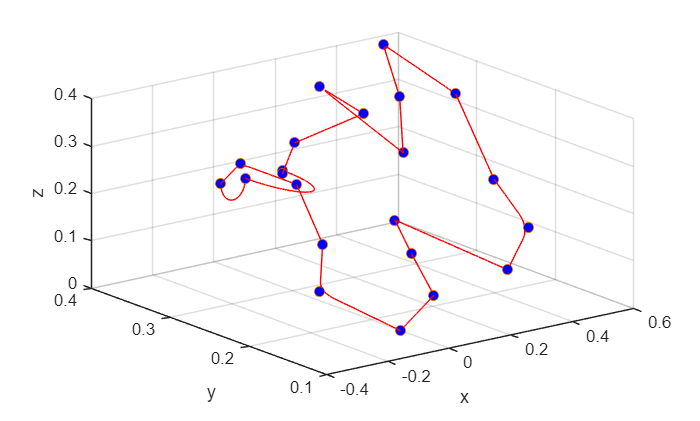

figure
plot(t,out.qdot_sec.signals.values(1,:), 'black')

hold on
plot(t,out.qdot_sec.signals.values(2,:), 'blue')
hold on
plot(t,out.qdot_sec.signals.values(3,:), 'red')
hold on
plot(t,out.qdot_sec.signals.values(4,:), 'Color', [0.2 0.7 1.0])
hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\dot{q(t)}$', 'Interpreter', 'latex');
title('Joint variables velocities');
xlim([0 24*5])
legend('$\dot{q_1}$','$\dot{q_2}$','$\dot{q_3}$','$\dot{q_4}$','Interpreter', 'latex')
grid on

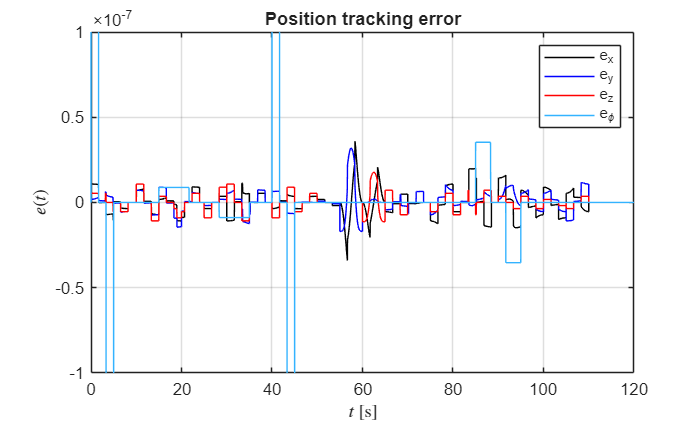

figure
plot(t,out.qdotdot_sec.signals.values(1,:), 'black')
hold on
plot(t,out.qdotdot_sec.signals.values(2,:), 'blue')
hold on

plot(t,out.qdotdot_sec.signals.values(3,:), 'red')
hold on

w_inv =     0.2672    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673    0.2673


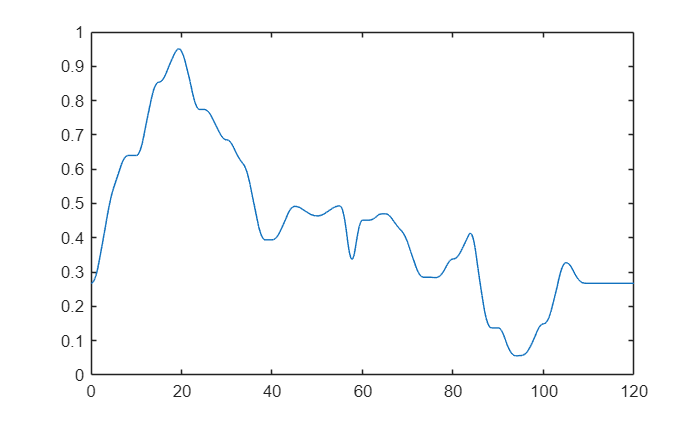

plot(t,out.qdotdot_sec.signals.values(4,:), 'Color', [0.2 0.7 1.0])

hold on
xlabel('$t$ [s]', 'Interpreter', 'latex');
ylabel('$\ddot{q(t)}$', 'Interpreter', 'latex');
title('Joint variables accelerations');
xlim([0 24*5])
legend('$\ddot{q_1}$','$\ddot{q_2}$','$\ddot{q_3}$','$\ddot{q_4}$','Interpreter', 'latex')
grid on
qd = timeseries(out.q_sec.signals.values(:,:),t);
qddot = timeseries(out.qdot_sec.signals.values(:,:),t);
qddotdot = timeseries(out.qdotdot_sec.signals.values(:,:),t);

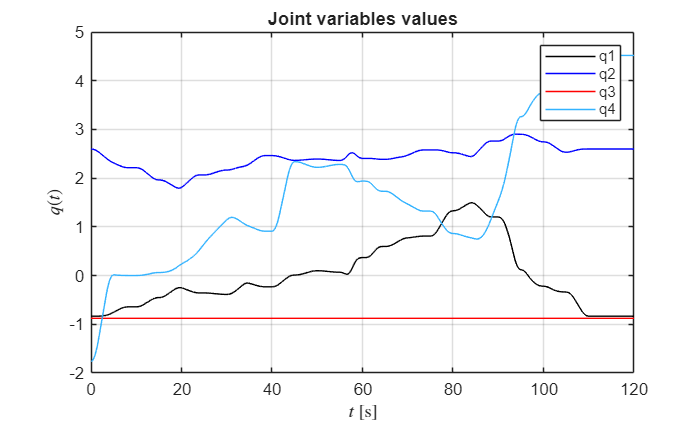

figure
plot(t,out.xe_sec.signals.values(1,:), 'black')
hold on
plot(t,out.xe_sec.signals.values(2,:), 'blue')
hold on
plot(t,out.xe_sec.signals.values(3,:), 'red')
hold on
plot(t,out.xe_sec.signals.values(4,:), 'y')
hold on
xlabel('t');
legend('x','y','z','phi')
xlim([0 24*5])
grid on

figure
plot3(out.xe_sec.signals.values(1,:),out.xe_sec.signals.values(2,:),out.xe_sec.signals.values(3,:), 'r')
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','b')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

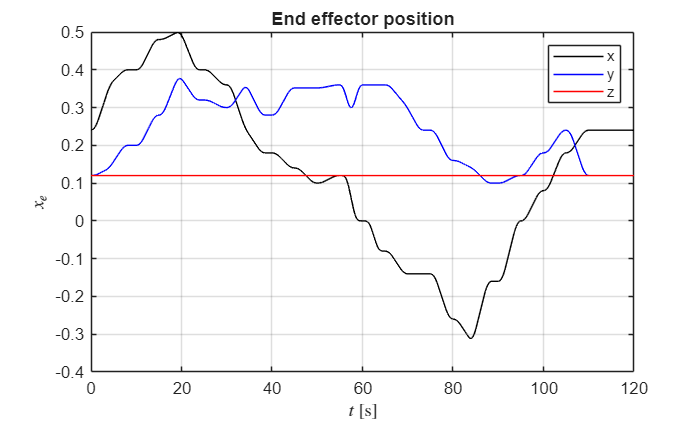

figure
plot(t,out.e_sec.signals.values(1,:), 'black')
hold on
plot(t,out.e_sec.signals.values(2,:), 'blue')
hold on
plot(t,out.e_sec.signals.values(3,:), 'red')
hold on

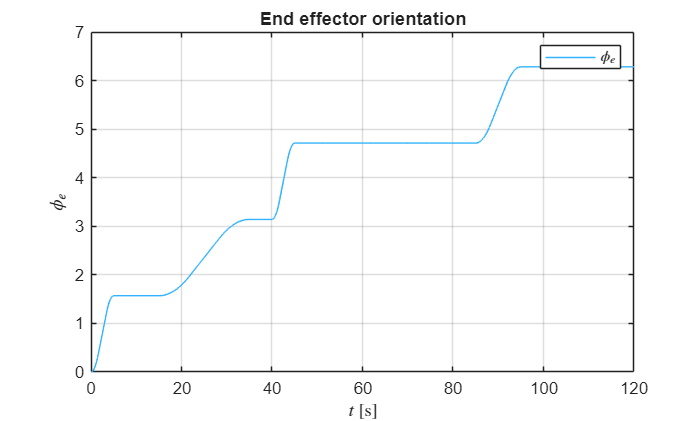

plot(t,out.e_sec.signals.values(4,:), 'Color', [0.2 0.7 1.0])
hold on
xlabel('t');
ylabel('e');
xlim([0 24*5])
legend('e_x','e_y','e_z','e_{\phi}')
grid on


xlim([0 120])
ylim([-3e-5 3e-5])

## Robust joint-space control

Kp_c = diag([700 1000 5000 400]);
Kd_c = diag([30 3 20 10]);
D = [zeros(4,4);eye(4)];
Q = [eye(4)*10 eye(4)*1000;
    eye(4)*1000 eye(4)*10];

eps = 0.1;

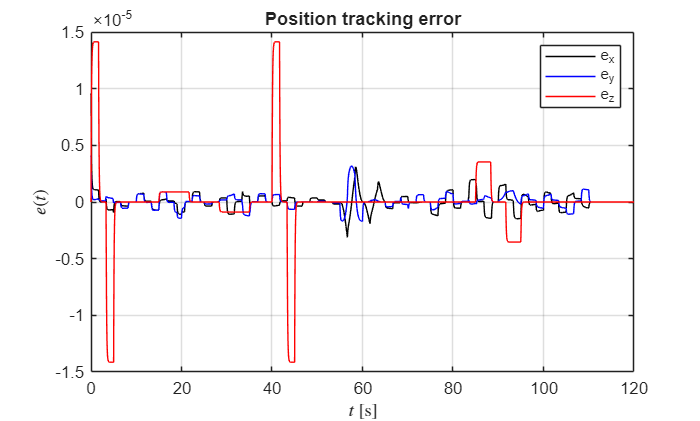

rho_vers = 3;
ml = 5; % Extra mass on the prismatic axis [kg]


out=sim("robust_joint_space_control.slx");

figure
plot(t,out.qcont.signals.values(:,:))
xlabel('t');
legend('q1','q2','q3','q4')
xlim([0 24*5])
grid on
hold on

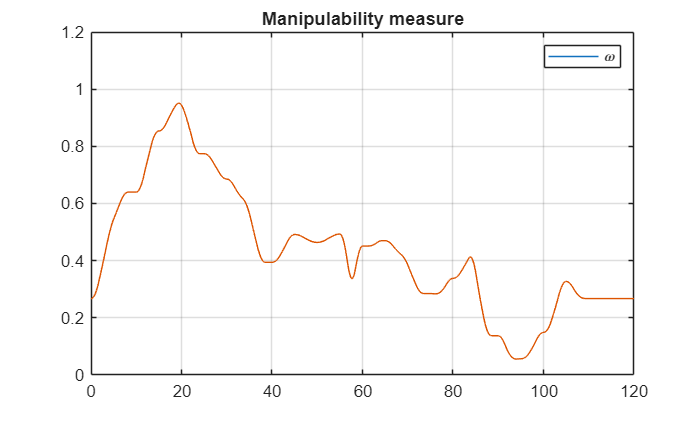

figure
plot(out.control.time,out.control.signals.values(1,:), 'black')
hold on
plot(out.control.time,out.control.signals.values(2,:), 'blue')
hold on

plot(out.control.time,out.control.signals.values(4,:), 'red')
hold on
xlim([0.0 24*5])
ylim([-4 4])
xlabel('t[s]','Interpreter','latex');
ylabel('$\tau(t)$','Interpreter','latex')
legend('$\tau_1$','$\tau_2$','$\tau_4$','Interpreter','latex');
title('Joint 1-2-4 torques');
grid on
hold on

figure
plot(out.control.time,out.control.signals.values(3,:), 'Color',[1 0.5 0])
xlabel('t[s]','Interpreter','latex');
ylabel('$\tau(t)$','Interpreter','latex')
title('Joint 3 torque');
xlim([0 24*5])
grid on
legend('$\tau_3$','Interpreter','Latex');

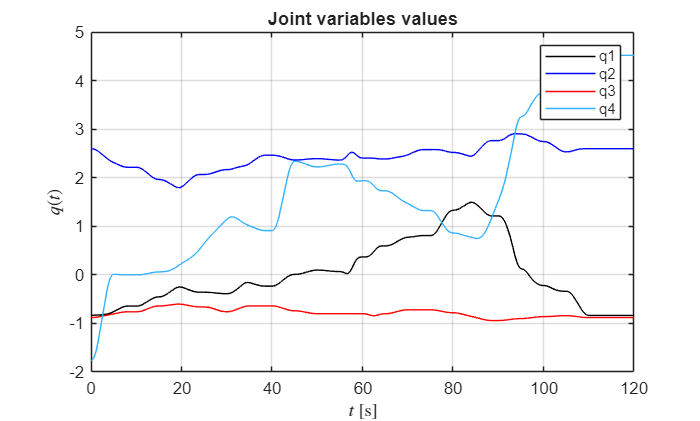

figure
plot(out.qerror.time,out.qerror.signals.values(1,:), 'black')

hold on
plot(out.qerror.time,out.qerror.signals.values(2,:), 'blue')
hold on
plot(out.qerror.time,out.qerror.signals.values(4,:), 'red')
hold on
legend('error\_q_1','error\_q_2','error\_q_4')
xlim([0 24*5])
xlabel('t[s]','Interpreter','latex');
ylabel('e(t)','Interpreter','latex');
title('Joint 1-2-4 position tracking error');
grid on

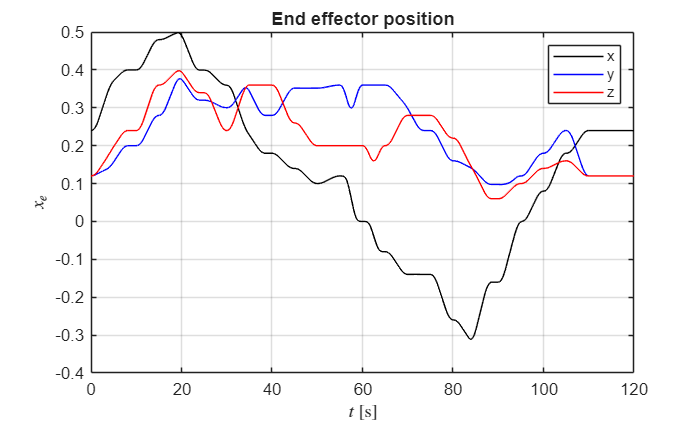

figure
plot(out.qerror.time,out.qerror.signals.values(3,:), 'red')
hold on

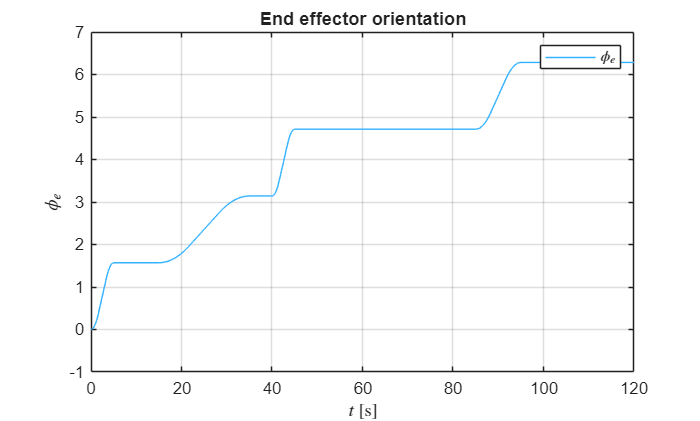

legend('error\_q_3')
xlim([0 24*5])
xlabel('t[s]','Interpreter','latex');
ylabel('e(t)','Interpreter','latex');
title('Joint 3 position tracking error');
grid on

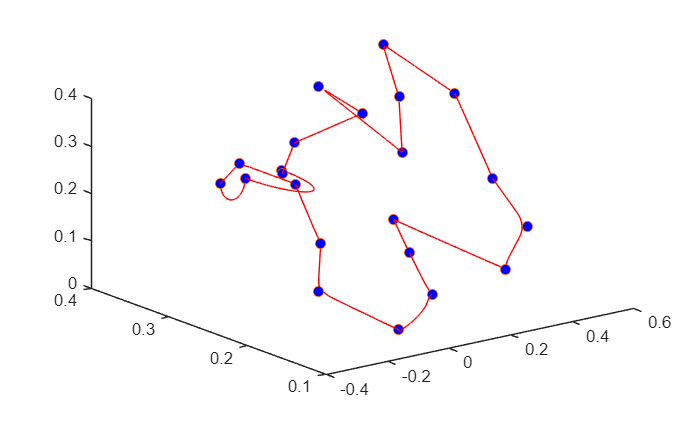

figure
plot(t,out.xecont.signals.values(:,:))
xlim([0 24*5])
xlabel('t');
grid on
legend('x','y','z','phi')

figure
plot3(out.xecont.signals.values(1,:),out.xecont.signals.values(2,:),out.xecont.signals.values(3,:), 'r')
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','b')

## Adaptive joint-space control

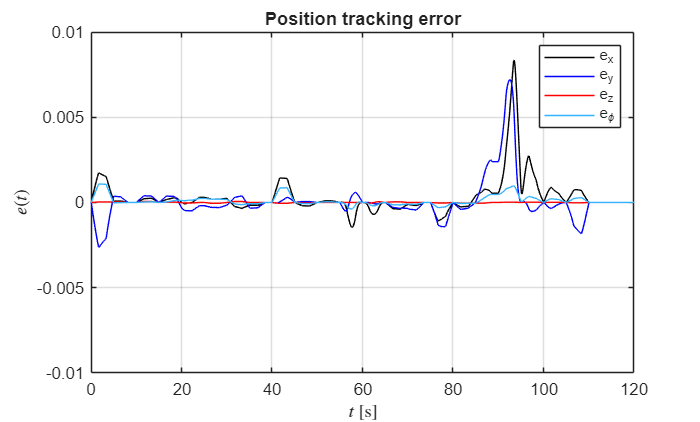

% The update law uses the inverse gain. A small payload entry speeds up its adaptation.
lambda=diag([80,80,80,80]);
K_pi=diag([10,10,10,10,10,10,10,10,10,10,10,0.001,10,10,10]);

Kd_c_ad=diag([400,400,400,400]);

ml1=20;
ml2=20;
ml3=10;
ml4=0;
Il1=4;
Il2=4;

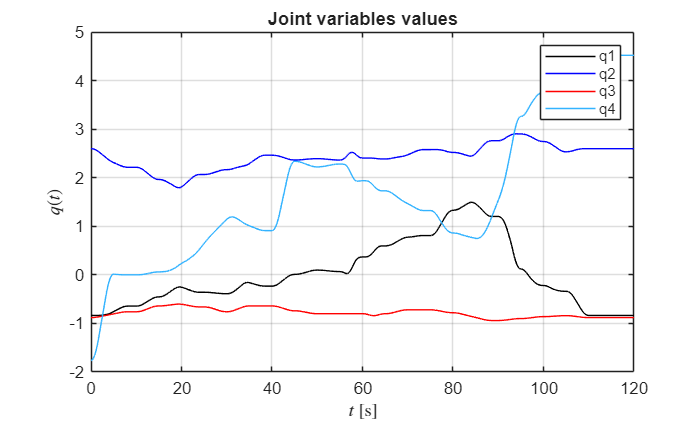

Il4=1;
kr1=1;
kr2=1;
kr3=50;
kr4=20;
Im1=0.01;
Im2=0.01;
Im3=0.005;
Im4=0.001;
Fm1=0.00005;
Fm2=0.00005;
Fm3=0.01;
Fm4=0.005;

pi0=[ml1 Il1 Im1 Fm1 ml2 Il2 Im2 Fm2 ml3 Im3 Fm3 ml4 Il4 Im4 Fm4]';

out=sim("adaptive_joint_space_control.slx");

figure
plot(t,out.qcontad.signals.values(:,:))
legend('q1','q2','q3','q4')
xlabel('t');
xlim([0 24*5])

grid on

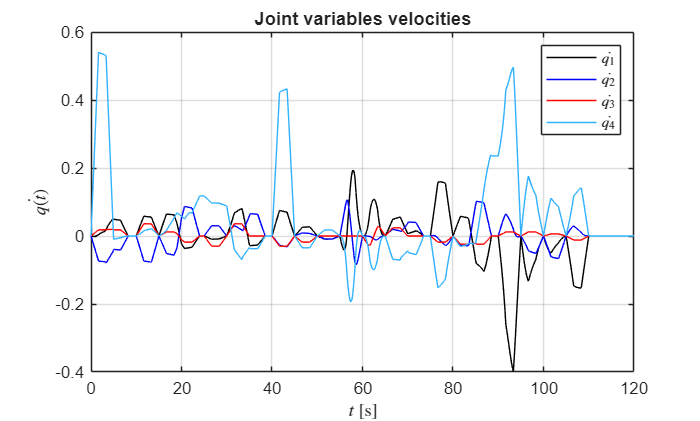

figure
plot(out.controlad.time,out.controlad.signals.values(1,:), 'black')
hold on
plot(out.controlad.time,out.controlad.signals.values(2,:), 'blue')
hold on
plot(out.controlad.time,out.controlad.signals.values(4,:), 'red')
hold on
xlim([0.0 24*5])
ylim([-4 4])
xlabel('t[s]','Interpreter','latex');
ylabel('$\tau(t)$','Interpreter','latex')
legend('$\tau_1$','$\tau_2$','$\tau_4$','Interpreter','latex');
title('Joint 1-2-4 torques');
grid on
hold on

figure
plot(out.controlad.time,out.controlad.signals.values(3,:), 'Color',[1 0.5 0])
xlabel('t[s]','Interpreter','latex');
ylabel('$\tau(t)$','Interpreter','latex')
title('Joint 3 torque');
xlim([0 24*5])
grid on
legend('$\tau_3$','Interpreter','Latex');

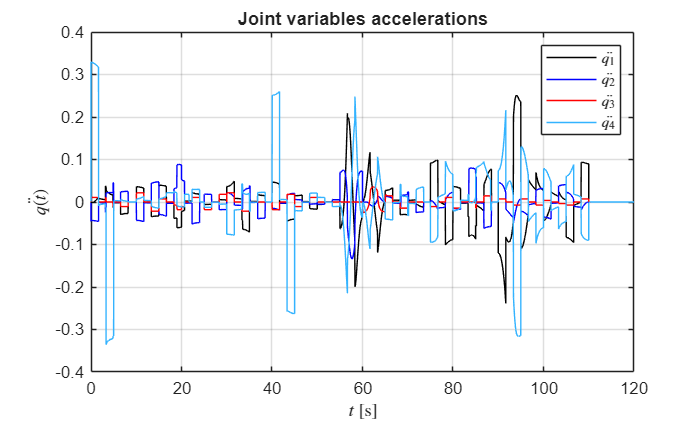

figure
plot(out.qerrorad.time,out.qerrorad.signals.values(1,:), 'black')
hold on
plot(out.qerrorad.time,out.qerrorad.signals.values(2,:), 'blue')
hold on
plot(out.qerrorad.time,out.qerrorad.signals.values(4,:), 'red')
hold on

legend('error\_q_1','error\_q_2','error\_q_4')
xlim([0 24*5])
xlabel('t[s]','Interpreter','latex');
ylabel('e(t)','Interpreter','latex');
title('Joint 1-2-4 position tracking error');
grid on
figure
plot(out.qerrorad.time,out.qerrorad.signals.values(3,:), 'red')
hold on
legend('error\_q_3')
xlim([0 24*5])
xlabel('t[s]','Interpreter','latex');
ylabel('e(t)','Interpreter','latex');
title('Joint 3 position tracking error');
grid on

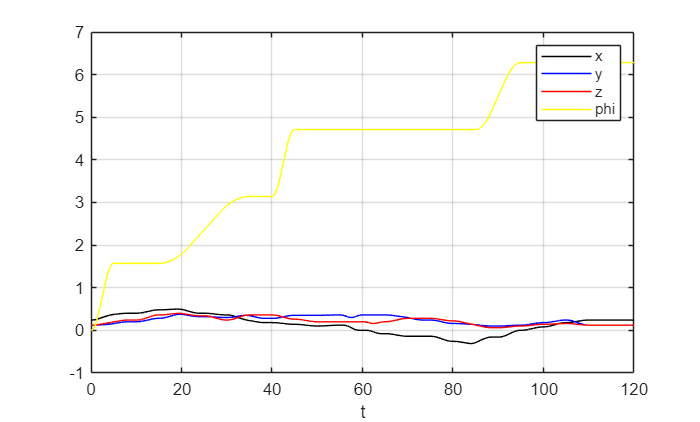

figure
plot(t,out.xecontad.signals.values(:,:))

xlabel('t');
xlim([0 24*5])
legend('x','y','z','phi')
grid on

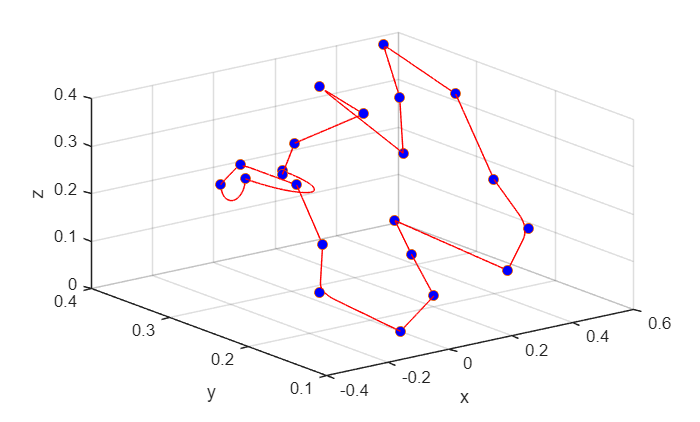

figure
plot(out.picappuccio.time,out.picappuccio.signals.values(12,:), 'red')
hold on
xlabel('t')
xlim([0 24*5])

grid on
legend('ml4')

figure
plot3(out.xecontad.signals.values(1,:),out.xecontad.signals.values(2,:),out.xecontad.signals.values(3,:), 'r')
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','b')

plot3(p(1, via_points_indices), p(2, via_points_indices), p(3, via_points_indices), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
xlabel('x')
ylabel('y')
zlabel('z')
grid on

## Operational-space inverse dynamics

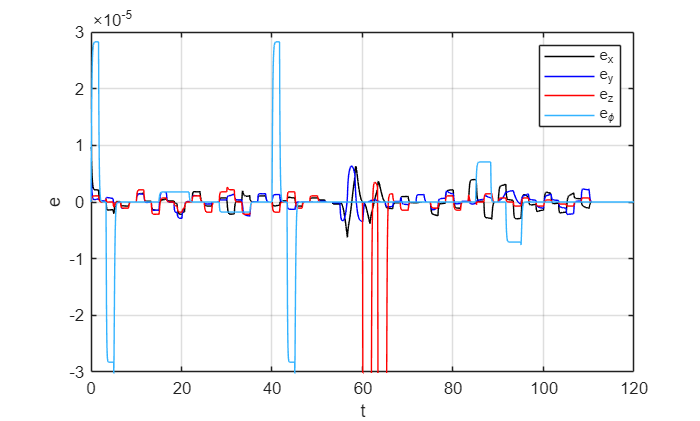

Kp_op = diag([50 50 50 50]);
Ki_op = diag([1 1 5 15]);
Kd_op = diag([15 20 30 4]);


out=sim("operational_space_inverse_dynamics");

figure
plot(out.qcontinvdin.time,out.qcontinvdin.signals.values(:,:))
legend('q1','q2','q3','q4')
xlabel('t');
xlim([0 24*5+6])
grid on

figure
plot(out.controlinvdin.time,out.controlinvdin.signals.values(1,:), 'black')
hold on
plot(out.controlinvdin.time,out.controlinvdin.signals.values(2,:), 'blue')
hold on
plot(out.controlinvdin.time,out.controlinvdin.signals.values(4,:), 'red')
hold on
xlim([0.0 24*5])
ylim([-4 4])
xlabel('t[s]','Interpreter','latex');
ylabel('$\tau(t)$','Interpreter','latex')
legend('$\tau_1$','$\tau_2$','$\tau_4$','Interpreter','latex');
title('Joint 1-2-4 torques');
grid on
hold on

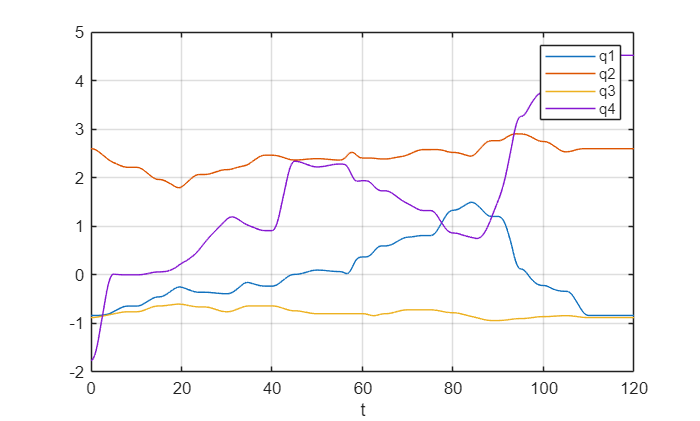

hold off
plot(out.controlinvdin.time,out.controlinvdin.signals.values(3,:), 'Color',[1 0.5 0])
xlabel('t[s]','Interpreter','latex');
ylabel('$\tau(t)$','Interpreter','latex')
title('Joint 3 torque');
xlim([0 24*5])

grid on
legend('$\tau_3$','Interpreter','Latex');

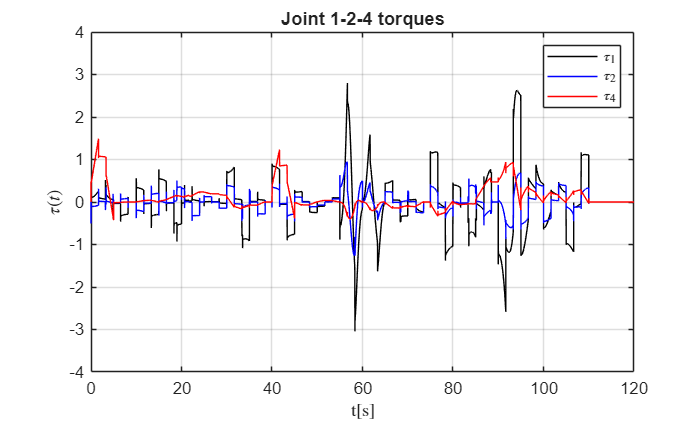

figure
plot(out.errorcontinv.time,out.errorcontinv.signals.values(1,:), 'black')
hold on
plot(out.errorcontinv.time,out.errorcontinv.signals.values(2,:), 'blue')
hold on
plot(out.errorcontinv.time,out.errorcontinv.signals.values(4,:), 'red')
hold on
legend('error\_q_1','error\_q_2','error\_q_4')
xlim([0 24*5])
xlabel('t[s]','Interpreter','latex');
ylabel('e(t)','Interpreter','latex');
title('Joint 1-2-4 position tracking error');
grid on

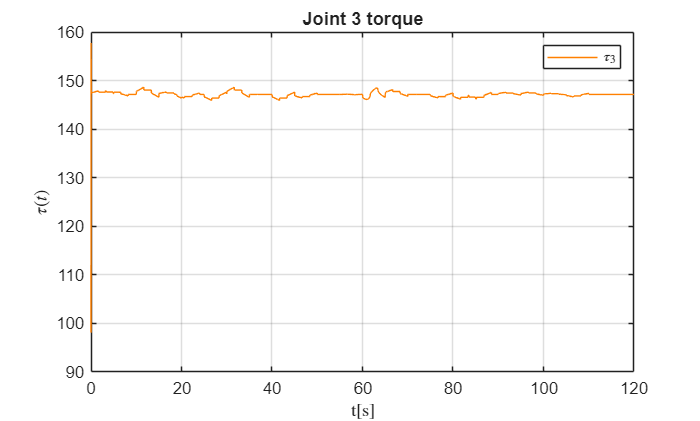

figure
plot(out.errorcontinv.time,out.errorcontinv.signals.values(3,:), 'red')
hold on
legend('error\_q_3')
xlim([0 24*5])
xlabel('t[s]','Interpreter','latex');
ylabel('e(t)','Interpreter','latex');
title('Joint 3 position tracking error');
grid on

MAX_ERR_DISO=[norm(out.errorcontinv.signals.values(1,:), Inf)
 norm(out.errorcontinv.signals.values(2,:), Inf)
 norm(out.errorcontinv.signals.values(3,:), Inf)
 norm(out.errorcontinv.signals.values(4,:), Inf)]

MAX_TAU_DISO=[norm(out.controlinvdin.signals.values(1,:), Inf)
 norm(out.controlinvdin.signals.values(2,:), Inf)
 norm(out.controlinvdin.signals.values(3,:), Inf)
 norm(out.controlinvdin.signals.values(4,:), Inf)]

ERR_REG_DISO=[out.errorcontinv.signals.values(1,78000) out.errorcontinv.signals.values(2,78000) out.errorcontinv.signals.values(3,78000) out.errorcontinv.signals.values(4,78000)]'

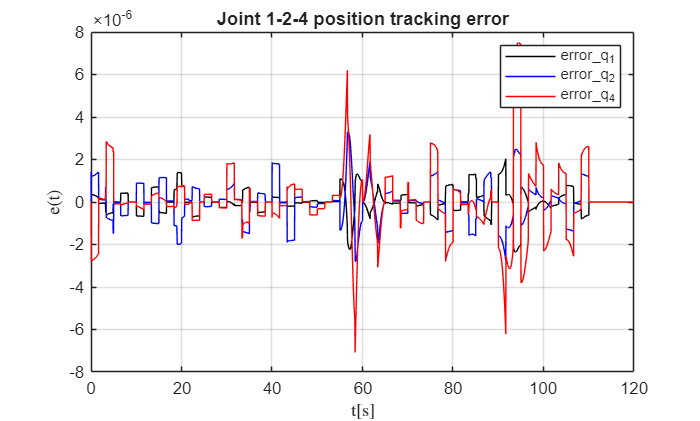

figure

plot(out.xeinvdin.time,out.xeinvdin.signals.values(:,:))
xlabel('t');
xlim([0 24*5+6])
legend('x','y','z','phi')
grid on

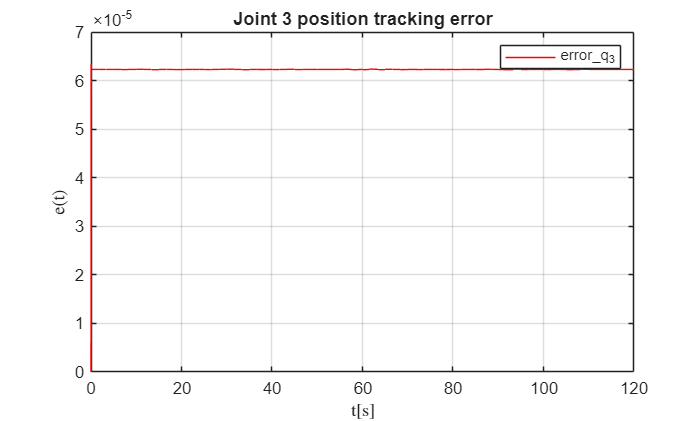

figure
plot3(out.xeinvdin.signals.values(1,:),out.xeinvdin.signals.values(2,:),out.xeinvdin.signals.values(3,:), 'r')
hold on
plot3(p(1,:),p(2,:),p(3,:),'o','MarkerFaceColor','b')

plot3(p(1, via_points_indices), p(2, via_points_indices), p(3, via_points_indices), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
xlabel('x')
ylabel('y')
zlabel('z')
grid on

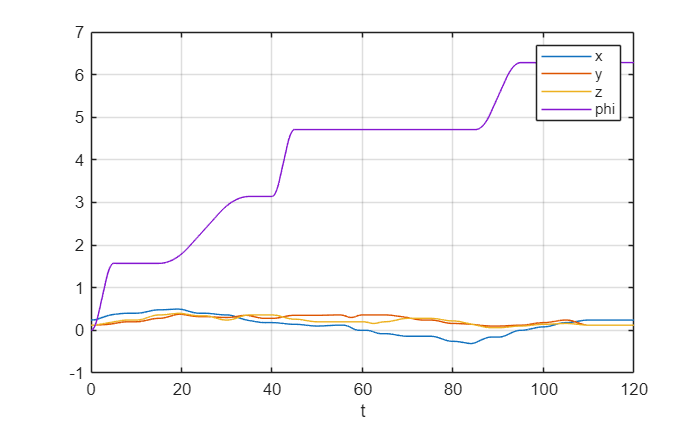

% Show one frame every 3 s of simulated motion.

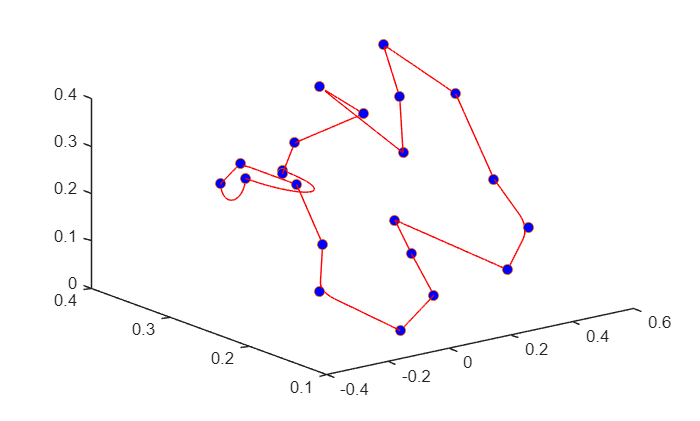

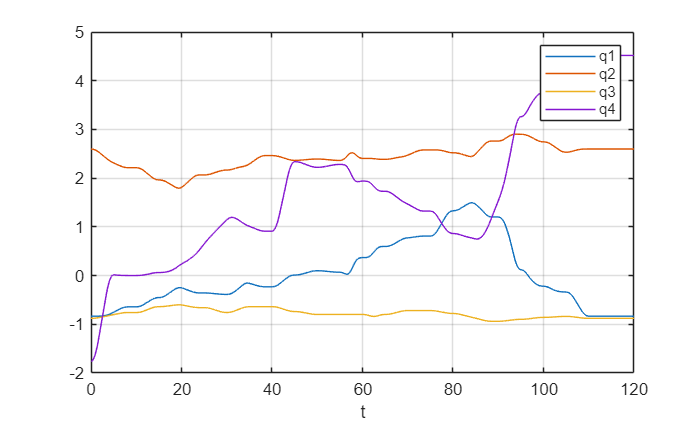

for t = 0:1:24
    clf;
    plot_scara_3d(out.qcontinvdin.signals.values(1,t*3000+1),out.qcontinvdin.signals.values(2,t*3000+1),out.qcontinvdin.signals.values(3,t*3000+1),out.qcontinvdin.signals.values(4,t*3000+1),P)
    pause(1)
end